problemIndex = int16(8);

A = [
    1, 0;
    7,-1
];

% Для отображений, где требуетсся вывести собственные вектора
% V = [1, 1; 0, 1];

pointsOld = [];
for x=1:0.5:5
    for y=1:0.5:3.5
        pointsOld = [pointsOld, [x; y]];
    end
end
% Для отображения 9 и 10
% theta = linspace(-pi, pi, 20);
% pointsOld = [cos(theta); sin(theta)];

pointsSize = 35

pointsSize = 35

color = pointsOld(2, :)

color =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    1.0000    1.5000


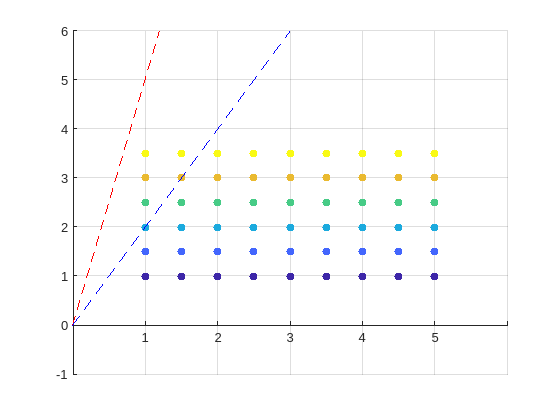

scatter(pointsOld(1, :), pointsOld(2, :), pointsSize, color, 'filled');
% Для отображений, где нужна прямая y = ax
hold on
line([-100, 100], [-500, 500], 'Color', 'red', 'LineStyle', '--');
line([-100, 100], [-200, 200], 'Color', 'blue', 'LineStyle', '--')
hold off

grid on
axis tight
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin')
axis([0 6 -1 6]);

exportgraphics(gcf, sprintf('plot_%.f_before.png', problemIndex))

pointsNew = A*pointsOld;

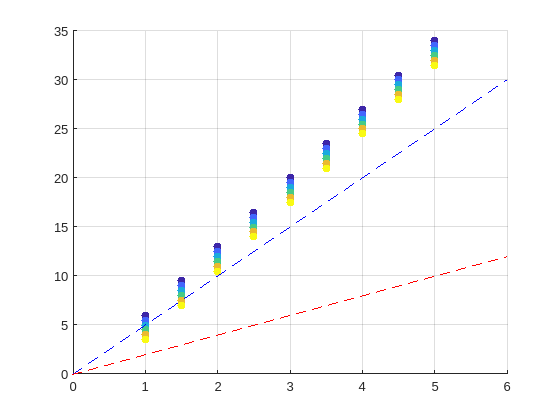

scatter(pointsNew(1, :), pointsNew(2, :), pointsSize, color, 'filled');
% Для отображений, где требуетсся вывести собственные вектора
hold on
line([-100, 100], [-500, 500], 'Color', 'blue', 'LineStyle', '--');
line([-100, 100], [-200, 200], 'Color', 'red', 'LineStyle', '--');
hold off

% Для отображений, где нужна прямая y = ax
% line([-100, 100], [-500, 500], 'Color', 'red', 'LineStyle', '--');

grid on
axis tight;
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin')
axis([0 6 0 35]);

exportgraphics(gcf, sprintf('plot_%.f_after.png', problemIndex))